mkdir (strcat(tempdir,'brainai'));
mkdir (strcat(tempdir,'brainai\\','unzip'));
mkdir (strcat(tempdir,'brainai\\','unzip\\','maskOutput'));
unzipLocation= (strcat(tempdir,'brainai\\','unzip'));
unzip(task.location{1},unzipLocation)
resultLocation=strcat(tempdir,'brainai\\','unzip\\','maskOutput');
imagesLocation = fullfile(unzipLocation,'images',"*nii*");
images = dir(imagesLocation);

netLocation = task.location_1{1};
net=load(netLocation);
fields = fieldnames(net);
net = getfield(net,fields{1});


for i=1:length(images)
    counter = 0;
    
    
    imagefile = fullfile(images(i).folder, images(i).name);
    info = niftiinfo(imagefile);
    I = imwarp(niftiread(imagefile),info.Transform);
    O = zeros(size(I));
    orig_sz=[size(I,3),size(I,2)];
    for z=1:size(I,1)
        percentage = (i-1)/length(images)+z/size(I,1)/length(images);
        counter = counter + 1;
        if(mod(counter,40)==0)
            conn = dbconn();
            query = strcat('update tasks set percentage = ',int2str(ceil(100*percentage)),' where id = ',int2str(task.id),';');
            execute(conn,query);
            close(conn)
        end
        input_image = imresize(flip(squeeze(I(z,:,:))'),[224,224]);
        result=imresize(semanticseg(input_image,net),orig_sz);
        result = flip(result)';
        O(z,:,:)= single(result)==1;
    end
    O = single(imwarp(O,invert(info.Transform)));
    O = O(1:info.ImageSize(1),1:info.ImageSize(2),1:info.ImageSize(3));
    
    output_file_name = strsplit(images(i).name,'.');
    output_file_name = strcat(output_file_name{1},'_mask')
    niftiwrite(O,fullfile(resultLocation,output_file_name),info);
end

output_file_name = 'sub-A00028352_ses-NFB3_T1w_mask'

output_file_name = 'sub-A0028352_ses-NFB3_T1w_mask'

zip(task.location{1},{'*'},unzipLocation);%overwrite!!
rmdir(strcat(tempdir,'brainai'), 's')

conn = dbconn();
query = strcat('update tasks set percentage = 100 where id = ',int2str(task.id),';');
execute(conn,query);
close(conn)

[~,result]=semanticseg(imresize(I(:,:,100),[224,224]),net);

imshowpair(double(result),imresize(I(:,:,100),[224,224]),'blend')

imshow(imresize(I(:,:,100),[224,224])/300)

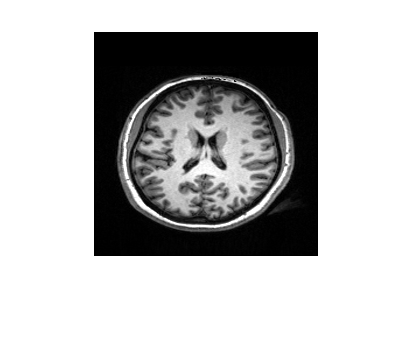

z=159;

input_image = squeeze(I(z,:,:))';
input_image = flip(input_image);
input_image=imresize(input_image,[224,224]);
imshow(input_image/400);

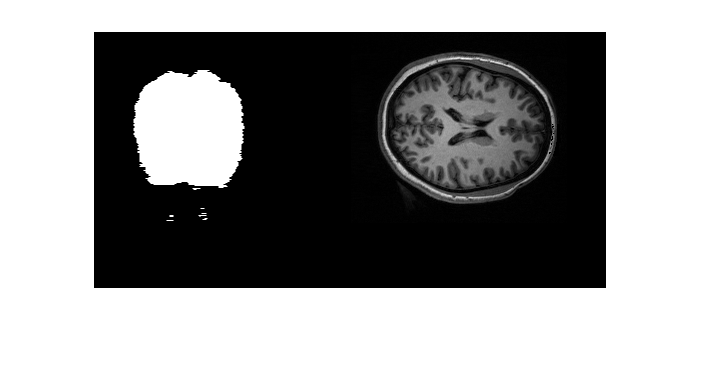

input_image=imresize(input_image,[size(I,3),size(I,2)]);
input_image = flip(input_image)';
imshowpair(squeeze(O(z,:,:)),squeeze(I(z,:,:)),'montage')